# * LCS HW6 Software Assignment*

## **Dr. Behzad Ahi**

**student: MohammadParsa Dini**

**student_id = 400101204**

***Problem 7:  ***

Here the bode plots of these transfer functions are depicted:

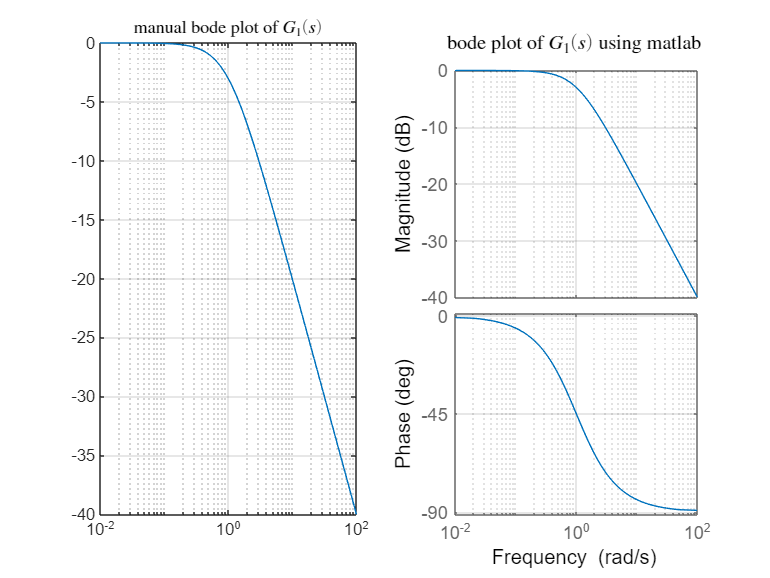

clear;
close all;
clc;

% G1
figure();
w = logspace(-2,2);
M1 = 1./(w*1i+1);
log_M1 = 20*log10(abs(M1));
subplot(1,2,1);
semilogx(w,log_M1);
grid on
title('manual bode plot of $G_1 (s)$',Interpreter='latex');
subplot(1,2,2);
G1 = tf(1 ,[1 1]);
bode(G1);
grid on
title('bode plot of $G_1 (s)$ using matlab',Interpreter='latex');

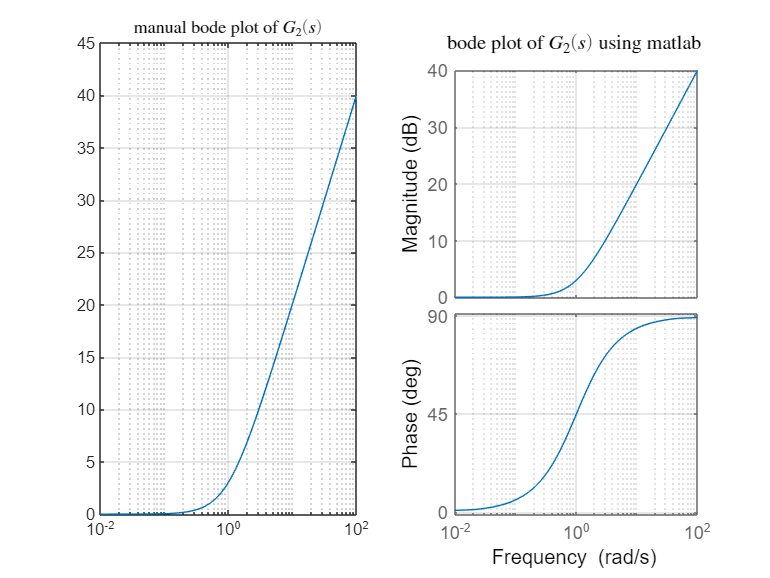

% G2 -------------------
clear;
figure();
w = logspace(-2,2);
M6 = (w*1i+1);
log_M2 = 20*log10(abs(M6));
subplot(1,2,1);
semilogx(w,log_M2);
grid on
title('manual bode plot of $G_2 (s)$',Interpreter='latex');
subplot(1,2,2);
G2 = tf([1 1],1);
bode(G2);
grid on
title('bode plot of $G_2 (s)$ using matlab',Interpreter='latex');

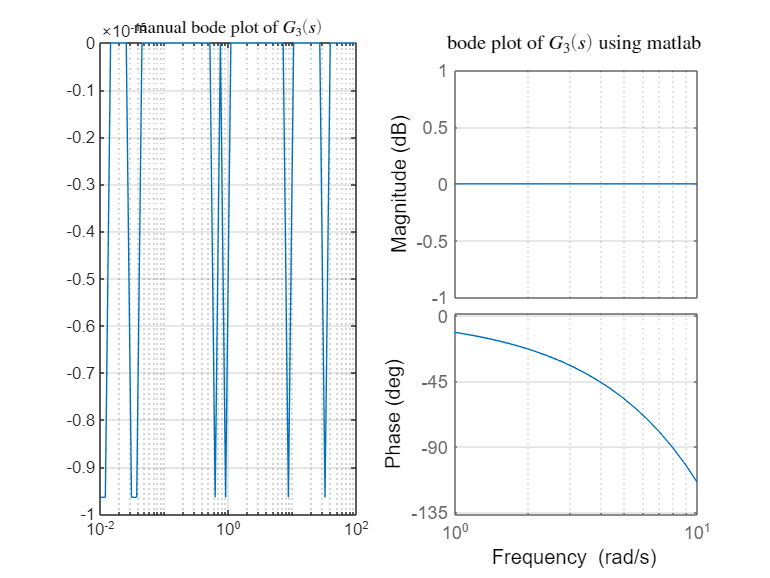

% G3 -------------------
clear;
figure();
w = logspace(-2,2);
M6 = exp(-0.2*w*1i);
log_M4 = 20*log10(abs(M6));
subplot(1,2,1);
semilogx(w,log_M4);
grid on
title('manual bode plot of $G_3 (s)$',Interpreter='latex');
subplot(1,2,2);
s = tf('s');
G6 = exp(-0.2*s);
bode(G6);
grid on
title('bode plot of $G_3 (s)$ using matlab',Interpreter='latex');

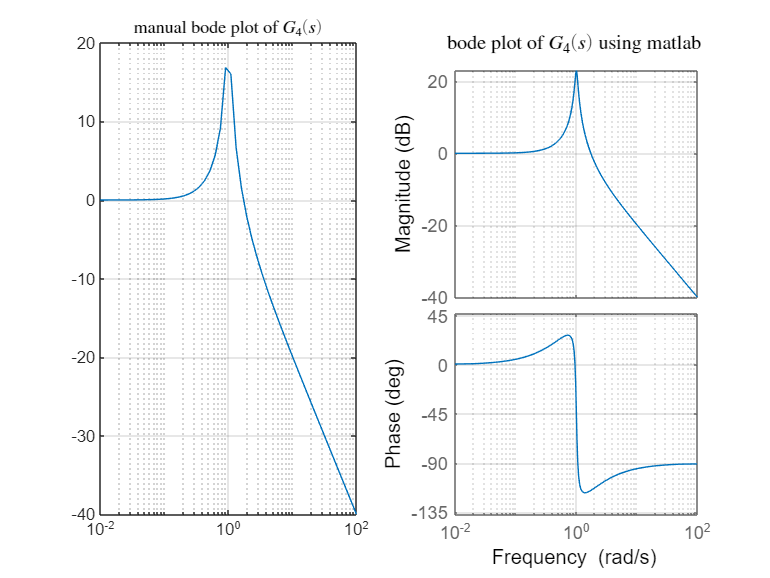

% G4 -------------------
clear;
figure();
w = logspace(-2,2);
M6 = (w*1i + 1)./(0.1*w*1i+1-w.*w);
log_M4 = 20*log10(abs(M6));
subplot(1,2,1);
semilogx(w,log_M4);
grid on
title('manual bode plot of $G_4 (s)$',Interpreter='latex');
subplot(1,2,2);
s = tf('s');
G6 = tf([1 1] ,[1 0.1 1]);
bode(G6);
grid on
title('bode plot of $G_4 (s)$ using matlab',Interpreter='latex');

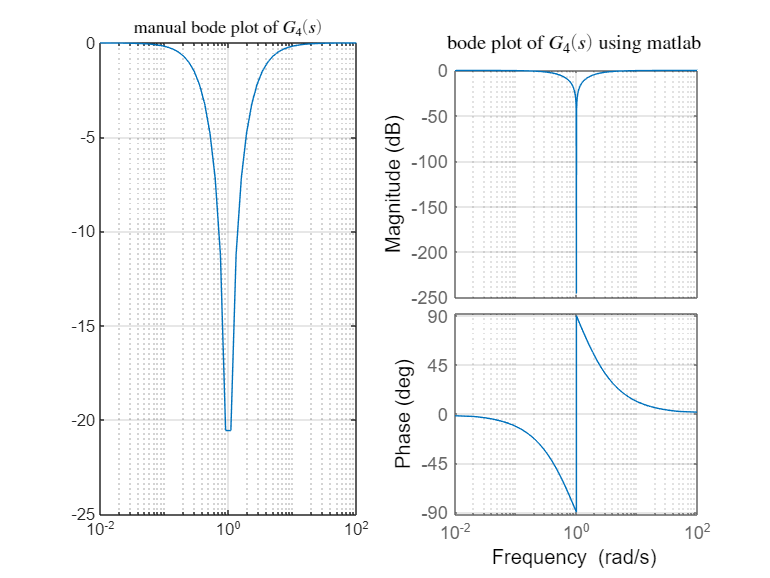

% G5 -------------------
clear;
figure();
w = logspace(-2,2);
M6 = (-1*w.*w + 1)./(-1*w.*w + 2*w*1i + 1);
log_M = 20*log10(abs(M6));
subplot(1,2,1);
semilogx(w,log_M);
grid on
title('manual bode plot of $G_4 (s)$',Interpreter='latex');
subplot(1,2,2);
s = tf('s');
G6 = tf([1 0 1] ,[1 2 1]);
bode(G6);
grid on
title('bode plot of $G_4 (s)$ using matlab',Interpreter='latex');

Both of these are resemblent, however we can see that matlab's plot is more accuarate around the singular point.

***Problem 8: ***

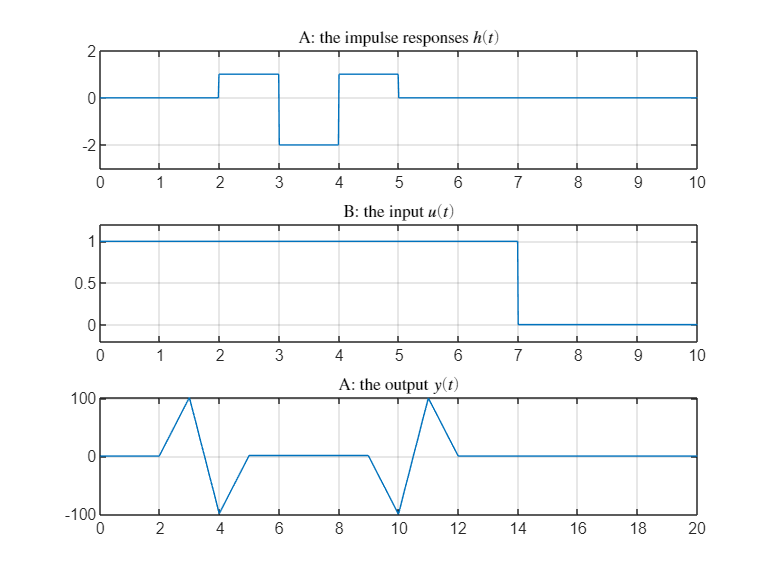

clear; 
close all;
clc;

% A -------------------
Ts = 0.01;                % sampling time step
t = 0 : Ts : 10;          % defining time  
u = zeros(size(t));       % unit step 
u(1:7/Ts) = 1;     
figure();
h = zeros(size(t));       % defining the impulse response
h(2/Ts:3/Ts) = 1;
h(3/Ts +1:4/Ts) = -2;
h(4/Ts +1:5/Ts) = 1;
subplot(3,1,1);
plot(t,h);
title('A: the impulse responses $h(t)$',Interpreter='latex');
ylim([-3 ,2]);
grid on;
subplot(3,1,2);
plot(t,u);
title('B: the input $u(t)$',Interpreter='latex');
grid on;
ylim([-.2, 1.2]);
subplot(3,1,3);
t1 = 0:0.01:20; 
plot(t1,conv(u,h));
title('A: the output $y(t)$',Interpreter='latex');
grid on;

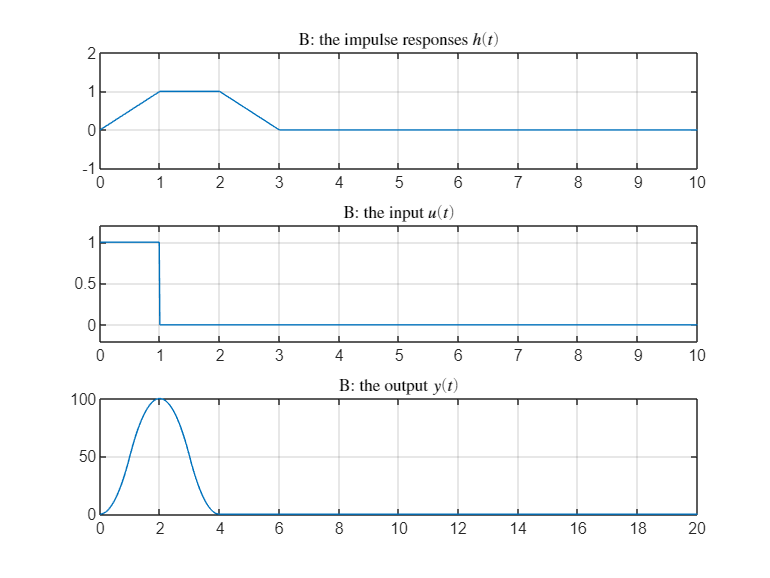

% B -------------------
Ts = 0.01;                % sampling time step
t = 0 : Ts : 10;          % defining time  
u = zeros(size(t));       % unit step 
u(1:1/Ts) = 1;     
figure();
h = zeros(size(t));       % defining the impulse response
h(1:1/Ts) = t(1:1/Ts);
h(1/Ts +1:2/Ts) = 1;
h(2/Ts +1:3/Ts) = 3 - t(2/Ts +1:3/Ts);
subplot(3,1,1);
plot(t,h);
title('B: the impulse responses $h(t)$',Interpreter='latex');
ylim([-1 2]);
grid on;
subplot(3,1,2);
plot(t,u);
title('B: the input $u(t)$',Interpreter='latex');
grid on;
ylim([-.2, 1.2]);
subplot(3,1,3);
t1 = 0:0.01:20; 
plot(t1,conv(u,h));
title('B: the output $y(t)$',Interpreter='latex');
grid on;

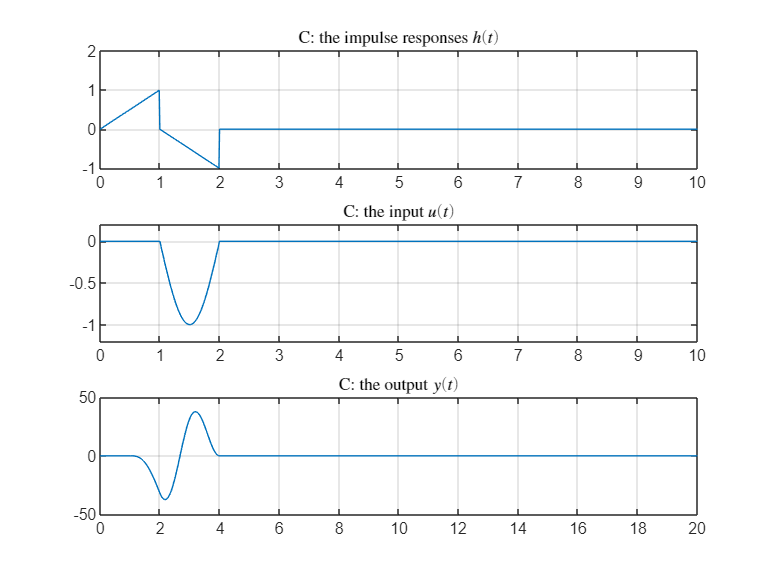

% C -------------------
Ts = 0.01;                % sampling time step
t = 0 : Ts : 10;          % defining time  
u = zeros(size(t));       % unit step 
%u(1+1/Ts,2/Ts) = sin(pi*t(1+1/Ts,2/Ts));   
u(101:200) = sin(pi*t(101:200));
figure();
h = zeros(size(t));       % defining the impulse response
h(1:1/Ts) = t(1:1/Ts);
h(1+1/Ts:2/Ts) = 1 - t(1+1/Ts:2/Ts);
subplot(3,1,1);
plot(t,h);
title('C: the impulse responses $h(t)$',Interpreter='latex');
ylim([-1 2]);
grid on;
subplot(3,1,2);
plot(t,u);
title('C: the input $u(t)$',Interpreter='latex');
grid on;
ylim([-1.2, .2])
subplot(3,1,3);
t1 = 0:0.01:20; 
plot(t1,conv(u,h));
title('C: the output $y(t)$',Interpreter='latex');
grid on;

***Problem 9: Part A***

In this case, $T_1(s) = \frac{1}{2s+1} \rightarrow 
T_ 1(t) = exp(-t/2)$ and we wish to truncate it from $t = T_s$, so the truncated signal becomes $M_1(t) = T_1(t) (u(t) - \exp(-T_s /2) u(t- T_s))$ which implies:

$M_1(s) = T_1(s) ( 1 - \exp(-T_s /2) \exp(-T_s s))
$. Since we wanted to truncate the signal in time domain, we must scale the shifted version of $\exp(-t/2)$ in order to let them cancel each other for all $t \geq T_s$.

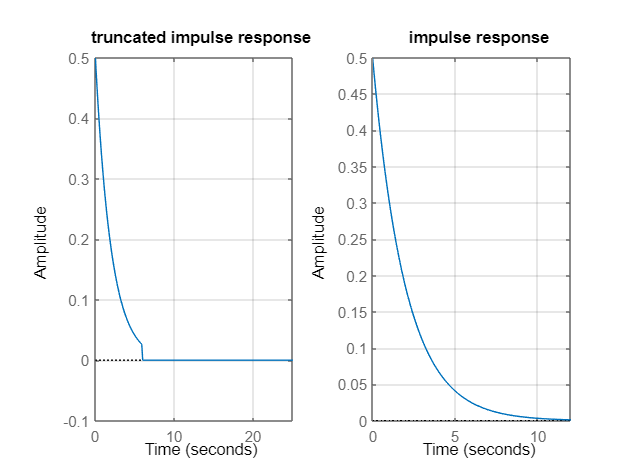

c = 3; 
s = tf('s'); 
T = 2*c;
M1 = (1 - exp(-0.5*T)*exp(-T*s) )/(2*s+ 1 );
T1 = 1/(2*s+1);

figure();
subplot(1,2,1);
impulse(M1);
title('truncated impulse response');
grid on;
subplot(1,2,2);
impulse(T1);
title('impulse response');
grid on;

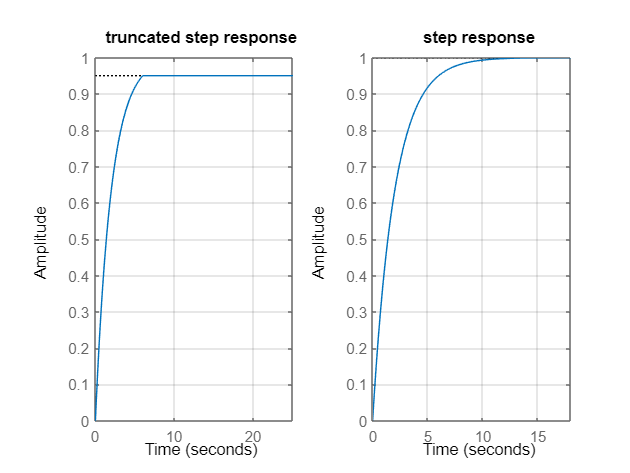


figure();
subplot(1,2,1);
step(M1);
title('truncated step response');
grid on;
subplot(1,2,2);
step(T1);
title('step response');
grid on;

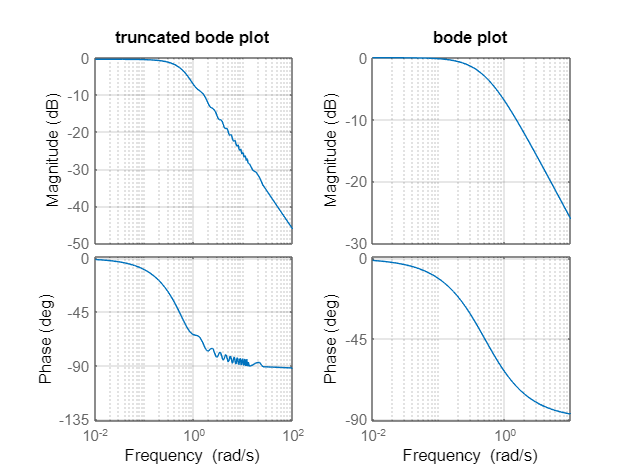


figure();
subplot(1,2,1);
bode(M1);
title('truncated bode plot');
grid on;
subplot(1,2,2);
bode(T1);
title('bode plot');
grid on;

It is obvious that when the signal gets truncated, it has a noisy behaviour with respect to the original version of the signal.

***Problem 9: Part B***

We have $T_2 (s) = \frac{1}{s^2 +s + 1}  \rightarrow T_2 (t)  = \frac{ 2 \exp(-t/2) \sin(\sqrt{3} t/2)}{\sqrt{3}}$. we have $\omega_n = 1, \zeta = 0.5$ and $T_s = \frac{4}{\zeta \omega_n}= 8$. In order to truncate the main signal, we can use a pulse signal as $h(t) = u(t) - u(t-T_s)$ which is laplace transform is $H(s) = \frac{1 -\exp(-T_s s)}{s}$ , therefore we need to convolve $H(s)$ and $T_2 (s)$ in $s$ domain, in order to do so, I've used a technique I;ve learnt in DSP course, we can map this continuous space into discrete Z space, and then using bilinar transform, convolve the coefficients and finally using conversion into s domain we get our truncated signal.

However, there is a better approach: we can actually, find the laplace transform of that signal:

$M_2 (t) = T_2 (t) (u(t) - u( t-T_s))
$ which  leads to 


$$M_2 (s) = \frac{1}{s^2 + s + 1} + \frac{- \exp(-T_s /2) }{j \sqrt{3} }  (  \frac{   \exp(-T_s (s - j\sqrt{3}/2) )}{ s + 1/2 - j\sqrt{3}/2 } + 
\frac{   \exp(-T_s (s + j\sqrt{3}/2) )}{ s + 1/2 + j\sqrt{3}/2 } )$$
  

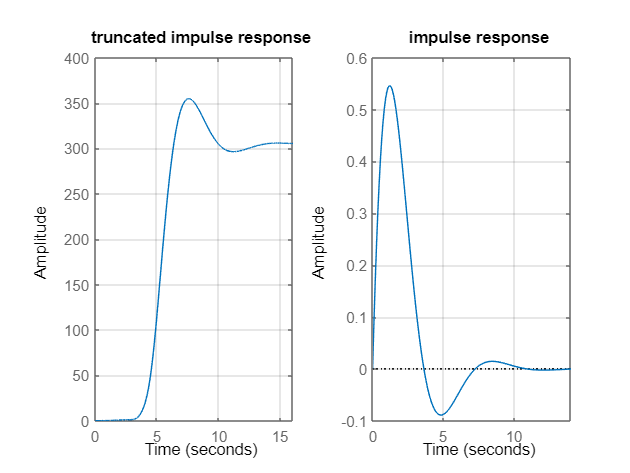

s = tf('s'); 
Ts = 8;
T2 = 1/(s^2 + s+1);
H = (1 -exp(-Ts*s))/s;
Td = 0.1; % Sampling period
z = tf('z',Td);
H1z = c2d(H,Td,'tustin');
H2z = c2d(T2,Td,'tustin');
[num1,den1] = tfdata(H1z,'v');
[num2,den2] = tfdata(H2z,'v');
num = conv(num1,num2);
den = conv(den1,den2);
Hz = tf(num,den,Td);
M2 = d2c(Hz,'tustin');

figure();
subplot(1,2,1);
impulse(M2);
title('truncated impulse response');
grid on;
subplot(1,2,2);
impulse(T2);
title('impulse response');
grid on;

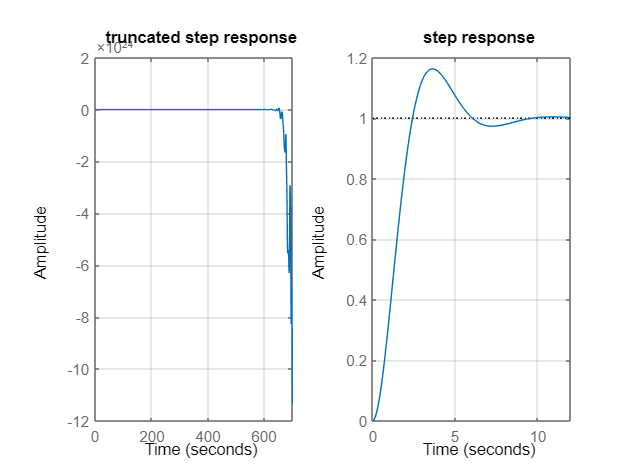

figure();
subplot(1,2,1);
step(M2);
title('truncated step response');
grid on;
subplot(1,2,2);
step(T2);
title('step response');
grid on;

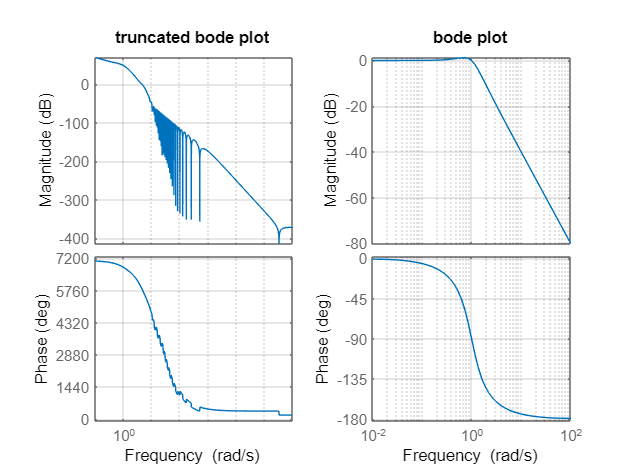

figure();
subplot(1,2,1);
bode(M2);
title('truncated bode plot');
grid on;
subplot(1,2,2);
bode(T2);
title('bode plot');
grid on;

As we can see, the signal is very much distorted this way...

Therfore, we don't really expect to get our time domain signals having resemblance

***Problem 10:***

We have 

Note that before running thos peace of code we need to simulate the other attatched file, so that it works properly.

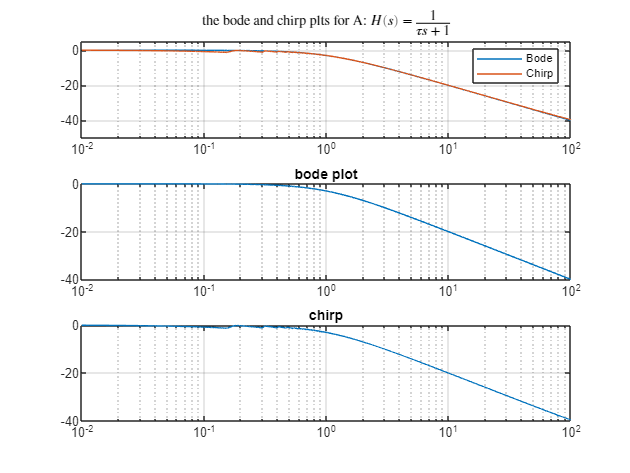

% 10 ----------------------------- A
H_s = tf(1,[1 1]);
simul1 = out.simout.Data;
w = linspace(0.01 , 100 , length(simul1));
h = reshape(bode(H_s,w),size(w));
figure();
subplot(3,1,1);
semilogx(w,20*log10(h));
hold on;
semilogx(w,20*log10(simul1));
grid on;   
title('the bode and chirp plts for A: $H(s) = \frac{1}{\tau s +1}$',Interpreter='latex');
ylim([-50 ,5]);
legend({'Bode' , 'Chirp'});
subplot(3,1,2);
semilogx(w,20*log10(h));
title('bode plot');
grid on;   
subplot(3,1,3);
semilogx(w,20*log10(simul1));
title('chirp');
grid on;   

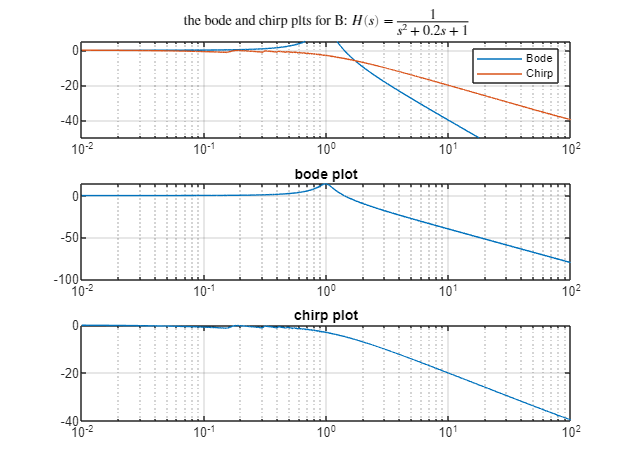

% 10 ----------------------------- B
H_s = tf(1,[1 0.2 1]);
simul1 = out.simout.Data;
w = linspace(0.01 , 100 , length(simul1));
h = reshape(bode(H_s,w),size(w));
figure();
subplot(3,1,1);
semilogx(w,20*log10(h));
hold on;
semilogx(w,20*log10(simul1));
grid on;   
title(['the bode and chirp plts for B: $H(s) = \frac{1}{s^2 + 0.2s +1}$'],Interpreter='latex');
ylim([-50 ,5]);
legend({'Bode' , 'Chirp'});
subplot(3,1,2);
semilogx(w,20*log10(h));
title('bode plot');
grid on;   
subplot(3,1,3);
semilogx(w,20*log10(simul1));
title('chirp plot');
grid on;   

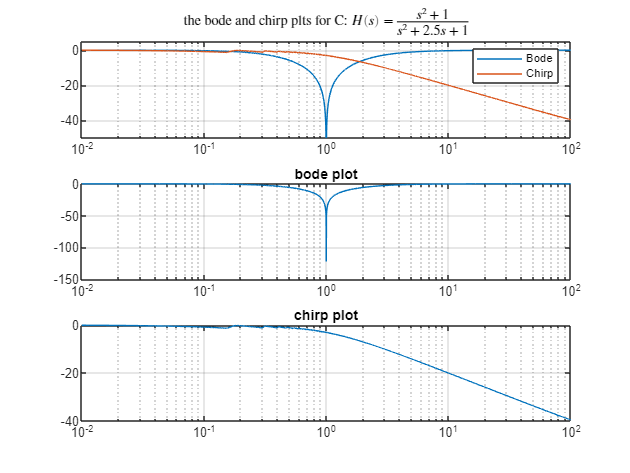

% 10 ----------------------------- C
H_s =  tf([1 0 1],[1 2.5 1]);
simul1 = out.simout.Data;
w = linspace(0.01 , 100 , length(simul1));
h = reshape(bode(H_s,w),size(w));
figure();
subplot(3,1,1);
semilogx(w,20*log10(h));
hold on;
semilogx(w,20*log10(simul1));
grid on;   
title(['the bode and chirp plts for C: $H(s) = \frac{s^2 +1}{s^2 + 2.5s +1}$'],Interpreter='latex');
ylim([-50 ,5]);
legend({'Bode' , 'Chirp'});
subplot(3,1,2);
semilogx(w,20*log10(h));
title('bode plot');
grid on;   
subplot(3,1,3);
semilogx(w,20*log10(simul1));
title('chirp plot');
grid on;   